clear

%%%%%%%%%%%%%%%%%%%
% Preparation
%%%%%%%%%%%%%%%%%%%
tspan=[0,100];
y0=[0,1];
N=10000;

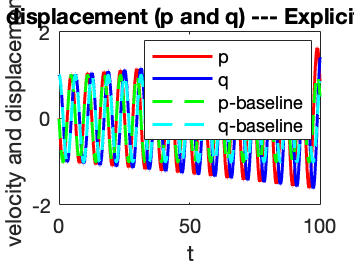

%%%%%%%%%%%%%%%%%%%%%%%
% Explicit Euler method
%%%%%%%%%%%%%%%%%%%%%%%
% Numerical solution
[t,y_euler_exp]=ode_euler_exp(@odefcn,tspan,y0,N);

% Analytical soltuion
X=zeros(2,length(t));
for i=1:length(t)
    X(:,i)=harmo_osc(t(i),y0(2),y0(1),1);
end

% Energy
energy=1/2*(y_euler_exp(:,1).*y_euler_exp(:,1)+y_euler_exp(:,2).*y_euler_exp(:,2));
energy_real=1/2*(X(2,:).*X(2,:)+X(1,:).*X(1,:));

% Plot
figure
plot(t,y_euler_exp(:,1),"Color",'r','LineWidth',1.5);hold on;
plot(t,y_euler_exp(:,2),"Color",'b','LineWidth',1.5);hold on;
plot(t,X(2,:),"Color",'g','LineWidth',1.5,'LineStyle','--');hold on;
plot(t,X(1,:),"Color",'c','LineWidth',1.5,'LineStyle','--');
xlabel('t');
ylabel('velocity and displacement');
legend('p','q','p-baseline','q-baseline');
title('Velocity and displacement (p and q) --- Explicit Euler Method');

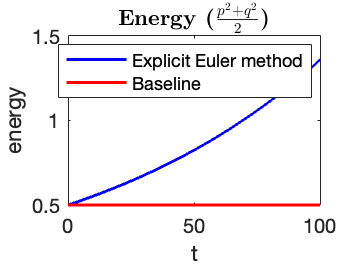


figure
plot(t,energy,"Color",'b','LineWidth',1.5,'LineStyle','-');hold on;
plot(t,energy_real,"Color",'r','LineWidth',1.5,'LineStyle','-');
xlabel('t');
ylabel('energy');
legend('Explicit Euler method','Baseline');
txt=title('\textbf{Energy ($\frac{p^2+q^2}{2}$)}');
set(txt,'Interpreter','latex');

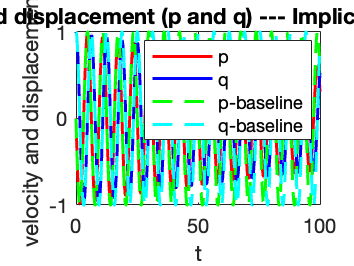

%%%%%%%%%%%%%%%%%%%%%%%
% Implicit Euler method
%%%%%%%%%%%%%%%%%%%%%%%
% Numerical solution
[t,y_euler_imp]=ode_euler_imp(@odefcn,tspan,y0,N);

% Analytical soltuion
X=zeros(2,length(t));
for i=1:length(t)
    X(:,i)=harmo_osc(t(i),y0(2),y0(1),1);
end

% Energy
energy=1/2*(y_euler_imp(:,1).*y_euler_imp(:,1)+y_euler_imp(:,2).*y_euler_imp(:,2));
energy_real=1/2*(X(2,:).*X(2,:)+X(1,:).*X(1,:));

% Plot
figure
plot(t,y_euler_imp(:,1),"Color",'r','LineWidth',1.5);hold on;
plot(t,y_euler_imp(:,2),"Color",'b','LineWidth',1.5);hold on;
plot(t,X(2,:),"Color",'g','LineWidth',1.5,'LineStyle','--');hold on;
plot(t,X(1,:),"Color",'c','LineWidth',1.5,'LineStyle','--');
xlabel('t');
ylabel('velocity and displacement');
legend('p','q','p-baseline','q-baseline');
title('Velocity and displacement (p and q) --- Implicit Euler Method');

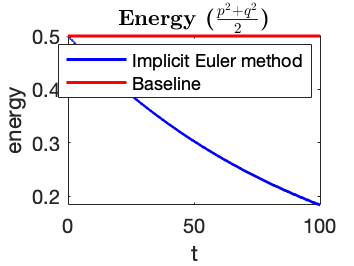


figure
plot(t,energy,"Color",'b','LineWidth',1.5,'LineStyle','-');hold on;
plot(t,energy_real,"Color",'r','LineWidth',1.5,'LineStyle','-');
xlabel('t');
ylabel('energy');
legend('Implicit Euler method','Baseline');
txt=title('\textbf{Energy ($\frac{p^2+q^2}{2}$)}');
set(txt,'Interpreter','latex');

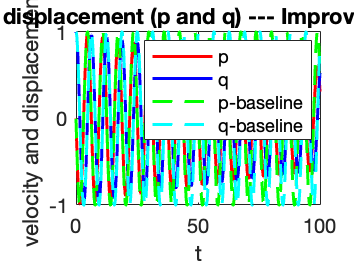

%%%%%%%%%%%%%%%%%%%%%%%
% Improved Euler method
%%%%%%%%%%%%%%%%%%%%%%%
% Numerical solution
[t,y_euler_improve]=ode_euler_improve(@odefcn,tspan,y0,N);

% Analytical soltuion
X=zeros(2,length(t));
for i=1:length(t)
    X(:,i)=harmo_osc(t(i),y0(2),y0(1),1);
end

% Energy
energy=1/2*(y_euler_improve(:,1).*y_euler_improve(:,1)+y_euler_improve(:,2).*y_euler_improve(:,2));
energy_real=1/2*(X(2,:).*X(2,:)+X(1,:).*X(1,:));

% Plot
figure
plot(t,y_euler_improve(:,1),"Color",'r','LineWidth',1.5);hold on;
plot(t,y_euler_improve(:,2),"Color",'b','LineWidth',1.5);hold on;
plot(t,X(2,:),"Color",'g','LineWidth',1.5,'LineStyle','--');hold on;
plot(t,X(1,:),"Color",'c','LineWidth',1.5,'LineStyle','--');
xlabel('t');
ylabel('velocity and displacement');
legend('p','q','p-baseline','q-baseline');
title('Velocity and displacement (p and q) --- Improved Euler Method');


figure
plot(t,energy,"Color",'b','LineWidth',1.5,'LineStyle','-');hold on;
plot(t,energy_real,"Color",'r','LineWidth',1.5,'LineStyle','-');
xlabel('t');
ylabel('energy');
legend('Implicit Euler method','Baseline');
txt=title('\textbf{Energy ($\frac{p^2+q^2}{2}$)}');
set(txt,'Interpreter','latex');

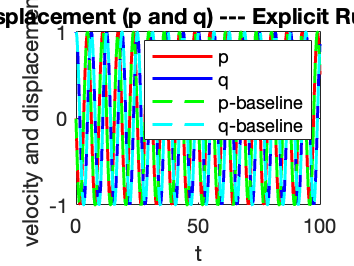

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Explicit Runge-Kutta method
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Numerical solution
[t,y_rk4_exp]=ode_expRK4(@odefcn,tspan,y0);

% Analytical soltuion
X=zeros(2,length(t));
for i=1:length(t)
    X(:,i)=harmo_osc(t(i),y0(2),y0(1),1);
end

% Energy
energy=1/2*(y_rk4_exp(1,:).*y_rk4_exp(1,:)+y_rk4_exp(2,:).*y_rk4_exp(2,:));
energy_real=1/2*(X(2,:).*X(2,:)+X(1,:).*X(1,:));

% Plot
figure
plot(t,y_rk4_exp(1,:),"Color",'r','LineWidth',1.5);hold on;
plot(t,y_rk4_exp(2,:),"Color",'b','LineWidth',1.5);hold on;
plot(t,X(2,:),"Color",'g','LineWidth',1.5,'LineStyle','--');hold on;
plot(t,X(1,:),"Color",'c','LineWidth',1.5,'LineStyle','--');
xlabel('t');
ylabel('velocity and displacement');
legend('p','q','p-baseline','q-baseline');
title('Velocity and displacement (p and q) --- Explicit Runge-Kutta Method');

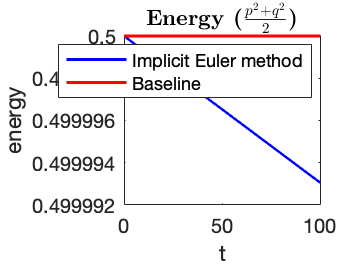


figure
plot(t,energy,"Color",'b','LineWidth',1.5,'LineStyle','-');hold on;
plot(t,energy_real,"Color",'r','LineWidth',1.5,'LineStyle','-');
xlabel('t');
ylabel('energy');
legend('Implicit Euler method','Baseline');
txt=title('\textbf{Energy ($\frac{p^2+q^2}{2}$)}');
set(txt,'Interpreter','latex');

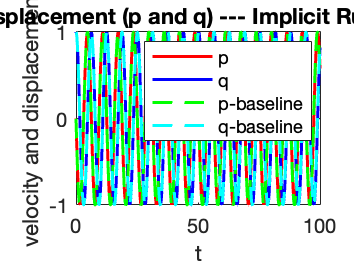

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Implicit Runge-Kutta method
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Numerical solution
[t,y_rk4_imp]=ode_impRK4(@odefcn,tspan,y0);

% Analytical soltuion
X=zeros(2,length(t));
for i=1:length(t)
    X(:,i)=harmo_osc(t(i),y0(2),y0(1),1);
end

% Energy
energy=1/2*(y_rk4_imp(1,:).*y_rk4_imp(1,:)+y_rk4_imp(2,:).*y_rk4_imp(2,:));
energy_real=1/2*(X(2,:).*X(2,:)+X(1,:).*X(1,:));

% Plot
figure
plot(t,y_rk4_imp(1,:),"Color",'r','LineWidth',1.5);hold on;
plot(t,y_rk4_imp(2,:),"Color",'b','LineWidth',1.5);hold on;
plot(t,X(2,:),"Color",'g','LineWidth',1.5,'LineStyle','--');hold on;
plot(t,X(1,:),"Color",'c','LineWidth',1.5,'LineStyle','--');
xlabel('t');
ylabel('velocity and displacement');
legend('p','q','p-baseline','q-baseline');
title('Velocity and displacement (p and q) --- Implicit Runge-Kutta Method');

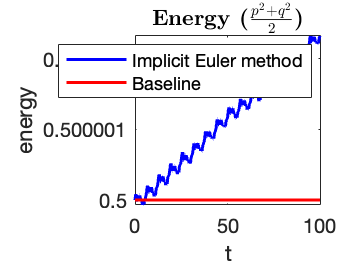


figure
plot(t,energy,"Color",'b','LineWidth',1.5,'LineStyle','-');hold on;
plot(t,energy_real,"Color",'r','LineWidth',1.5,'LineStyle','-');
xlabel('t');
ylabel('energy');
legend('Implicit Euler method','Baseline');
txt=title('\textbf{Energy ($\frac{p^2+q^2}{2}$)}');
set(txt,'Interpreter','latex');

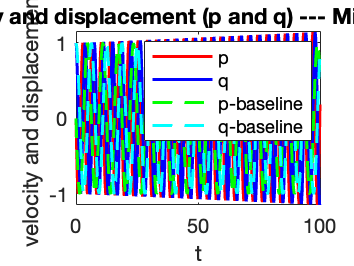

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Implicit Runge-Kutta method
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Numerical solution
[t,y_milne]=milne(@odefcn,tspan,y0);

% Analytical soltuion
X=zeros(2,length(t));
for i=1:length(t)
    X(:,i)=harmo_osc(t(i),y0(2),y0(1),1);
end

% Energy
energy=1/2*(y_milne(:,1).*y_milne(:,1)+y_milne(:,2).*y_milne(:,2));
energy_real=1/2*(X(2,:).*X(2,:)+X(1,:).*X(1,:));

% Plot
figure
plot(t,y_milne(:,1),"Color",'r','LineWidth',1.5);hold on;
plot(t,y_milne(:,2),"Color",'b','LineWidth',1.5);hold on;
plot(t,X(2,:),"Color",'g','LineWidth',1.5,'LineStyle','--');hold on;
plot(t,X(1,:),"Color",'c','LineWidth',1.5,'LineStyle','--');
xlabel('t');
ylabel('velocity and displacement');
legend('p','q','p-baseline','q-baseline');
title('Velocity and displacement (p and q) --- Milne Method');

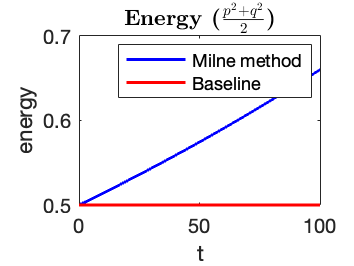


figure
plot(t,energy,"Color",'b','LineWidth',1.5,'LineStyle','-');hold on;
plot(t,energy_real,"Color",'r','LineWidth',1.5,'LineStyle','-');
xlabel('t');
ylabel('energy');
legend('Milne method','Baseline');
txt=title('\textbf{Energy ($\frac{p^2+q^2}{2}$)}');
set(txt,'Interpreter','latex');

function dydt=odefcn(t,y)                       % ODE to be solved
dydt=zeros(2,1);
dydt(1)=-y(2);
dydt(2)=y(1);
end

function X=harmo_osc(t,q0,p0,w)                 % Exact solution
A=[cos(w*t),1/w*sin(w*t);-w*sin(t),cos(w*t)];
X=A*[q0;p0];
end